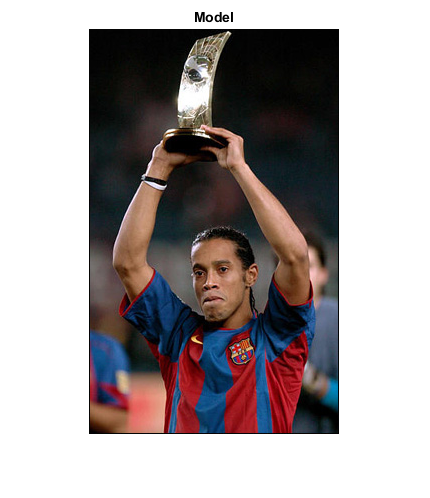

im = imread('model.jpg');
figure, imshow(im); title('Model');

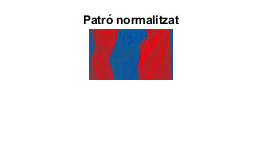


imd = im2double(im);
img = normalizeRGB(imd);
pattern = img(350:400,87:170,:);
figure, imshow(pattern); title('Patró normalitzat')


[model_red, model_blue] = histcountRB(pattern, 50);

%subplot(1,2,1);imshow(pattern); title('Non-normalised Mark');

%imnorm = normalizeRGB(im);
%pattnorm = imnorm(350:400,87:170,:);
%subplot(1,2,2);imshow(pattnorm(:,:,1)); title('Normalised Mark');
%[model_red, model_blue] = histcountRB(pattnorm,30);
%h = imhist(pattnorm,30);

%novaim = imread('barcelona/10.jpg');
%novaimg = im2double(novaim);
%novanorm = normalizeRGB(novaimg);

%res = computeQuadrants(model_red, model_blue,novanorm,20,0,2,2);

%figure, [model_red, model_blue] = histcountRB(pattnorm, 30); title('Histograma Red & Blue model');

Passem totes les imatges del barça (menys la que utilitzem com a model) per a extreure la similitud de cadascuna amb el model.

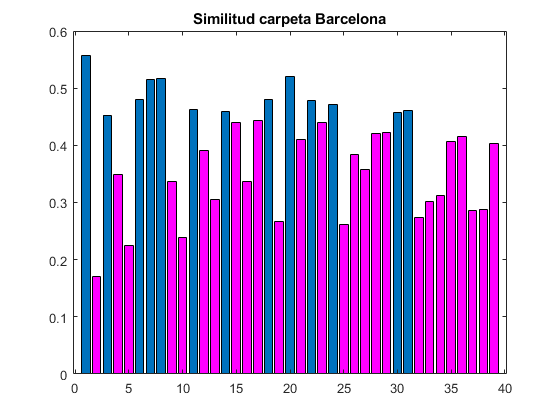

size = 39;
y = zeros(1,size);

for i = 1:size
    novaim = imread(['barcelona/',num2str(i),'.jpg']);
    novaimg = im2double(novaim);
    novanorm = normalizeRGB(novaimg);    
    [red,blue] = computeQuadrants(model_red, model_blue, novanorm, 50,0,2,2);
    y(i) = (red+blue)/2;
end

figure, 
b = bar(y,'FaceColor', "flat"); title('Similitud carpeta Barcelona');
count = 0;
for i = 1:size
    if y(i) < 0.45
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Total_reconegudes = [num2str(count/size *100),'%']

Total_reconegudes = '66.6667%'

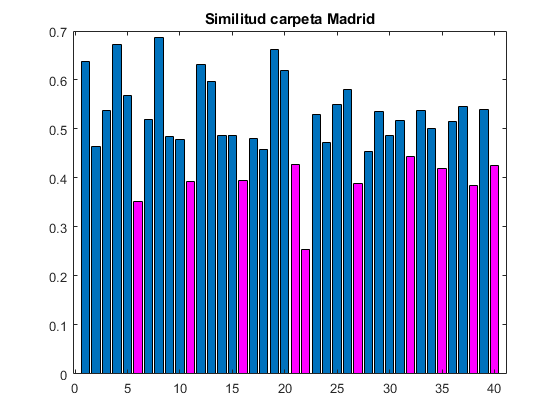

size=40;
y = zeros(1,size);

for i = 1:size
    novaim = imread(['madrid/',num2str(i),'.jpg']);
    novaimg = im2double(novaim);
    novanorm = normalizeRGB(novaimg);    
    [red,blue] = computeQuadrants(model_red, model_blue, novanorm, 50,0, 2, 2);
    y(i) = (red+blue)/2;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Madrid');

count = 0;
for i = 1:size
    if y(i) < 0.45
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end


Falsos_positius = [num2str(count/size *100),'%'] 

Falsos_positius = '25%'

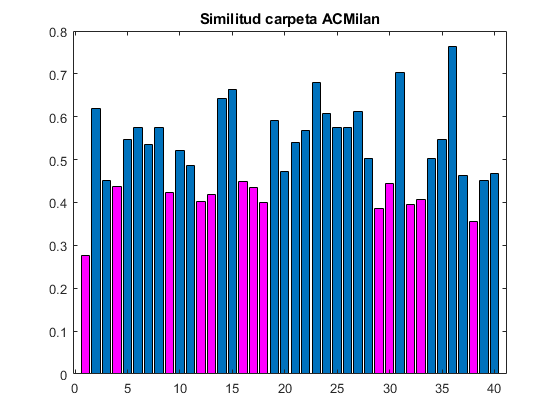

y = zeros(1,size);

for i = 1:size
    novaim = imread(['acmilan/',num2str(i),'.jpg']);
    novaimg = im2double(novaim);
    novanorm = normalizeRGB(novaimg);    
    [red,blue] = computeQuadrants(model_red, model_blue, novanorm, 50,0, 2, 2);
    y(i) = (red+blue)/2;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta ACMilan');

count = 0;
for i = 1:size
    if y(i) < 0.45
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Falsos_positius = [num2str(count/size *100),'%'] 

Falsos_positius = '33.3333%'

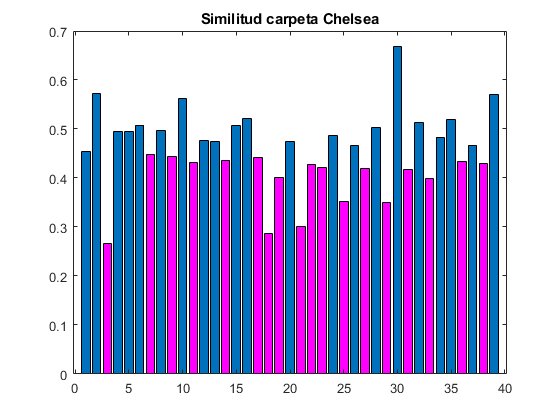

y = zeros(1,size);

for i = 1:size
    novaim = imread(['chelsea/',num2str(i),'.jpg']);
    novaimg = im2double(novaim);
    novanorm = normalizeRGB(novaimg);    
    [red,blue] = computeQuadrants(model_red, model_blue, novanorm, 50,0, 2, 2);
    y(i) = (red+blue)/2;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Chelsea');

count = 0;
for i = 1:size
    if y(i) < 0.45
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Falsos_positius = [num2str(count/size *100),'%'] 

Falsos_positius = '46.1538%'

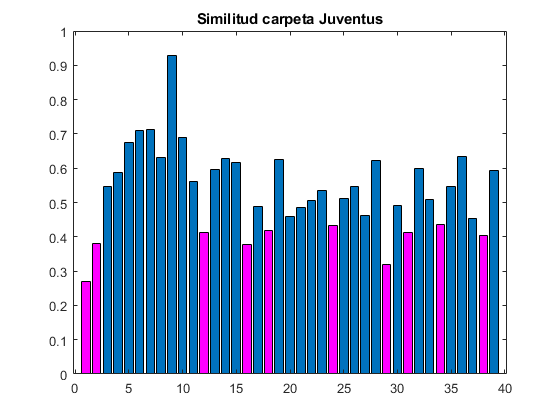

y = zeros(1,size);

for i = 1:size
    novaim = imread(['juventus/',num2str(i),'.jpg']);
    novaimg = im2double(novaim);
    novanorm = normalizeRGB(novaimg);    
    [red,blue] = computeQuadrants(model_red, model_blue, novanorm, 50,0, 2, 2);
    y(i) = (red+blue)/2;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Juventus');

count = 0;
for i = 1:size
    if y(i) < 0.45
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Falsos_positius = [num2str(count/size *100),'%'] 

Falsos_positius = '25.641%'

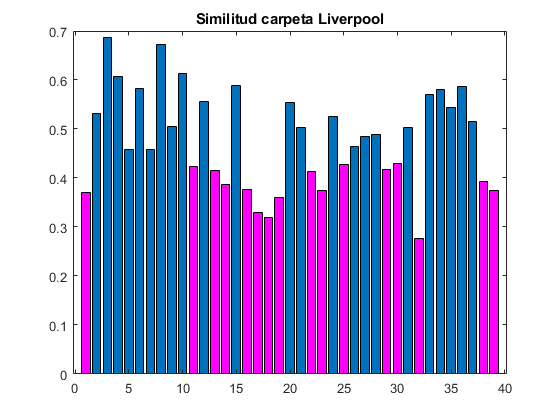

y = zeros(1,size);

for i = 1:size
    novaim = imread(['liverpool/',num2str(i),'.jpg']);
    novaimg = im2double(novaim);
    novanorm = normalizeRGB(novaimg);    
    [red,blue] = computeQuadrants(model_red, model_blue, novanorm, 50,0, 2, 2);
    y(i) = (red+blue)/2;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Liverpool');

count = 0;
for i = 1:size
    if y(i) < 0.45
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Falsos_positius = [num2str(count/size *100),'%'] 

Falsos_positius = '41.0256%'

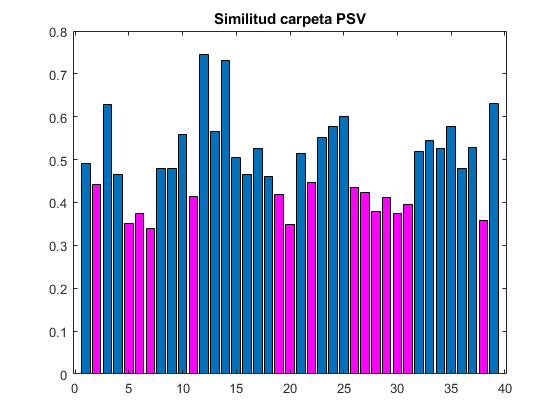

y = zeros(1,size);

for i = 1:size
    novaim = imread(['psv/',num2str(i),'.jpg']);
    novaimg = im2double(novaim);
    novanorm = normalizeRGB(novaimg);    
    [red,blue] = computeQuadrants(model_red, model_blue, novanorm, 50,0, 2, 2);
    y(i) = (red+blue)/2;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta PSV');

count = 0;
for i = 1:size
    if y(i) < 0.45
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Falsos_positius = [num2str(count/size *100),'%'] 

Falsos_positius = '38.4615%'

HSV

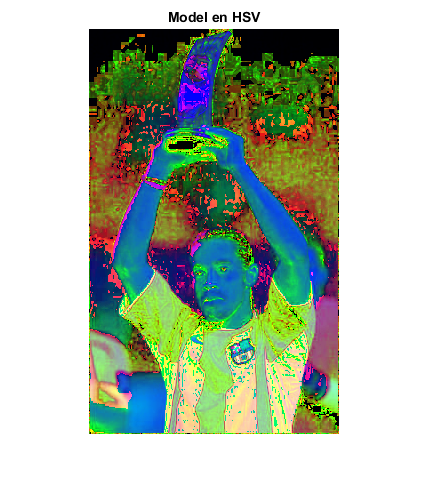

im = imread('model.jpg');
im = rgb2hsv(im);
figure, imshow(im); title('Model en HSV');

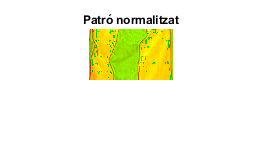

im = normalizeHSV(im);
pattern = im(350:400,87:170,:);
[mh, ms] = histcountHS(pattern, 50);
figure, imshow(pattern); title('Patró normalitzat');


newim = imread('barcelona/5.jpg');
newim = rgb2hsv(newim);
newim = normalizeHSV(newim);

%[h,s] = computeQuadrantsHSV(mh,ms,newim,50,0,2,2);



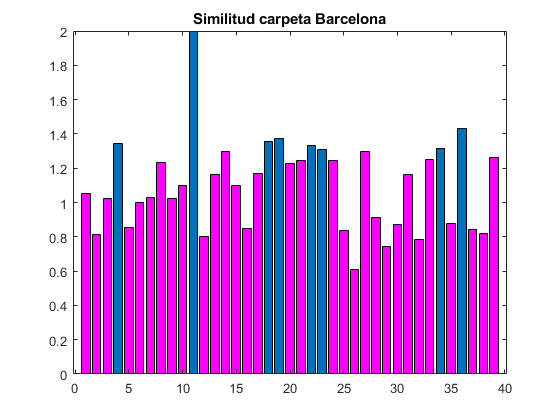

size = 39;
y = zeros(1,size);

for i = 1:size
    novaim = imread(['barcelona/',num2str(i),'.jpg']);
    novaimg = rgb2hsv(novaim);
    novanorm = normalizeHSV(novaimg);    
    [h,s] = computeQuadrantsHSV(mh,ms,novanorm,50,0,2,2);
    y(i) = (h+s)/2;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Barcelona');

count = 0;
for i = 1:size
    if y(i) < 1.3
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Total_reconegudes = [num2str(count/size *100),'%']

Total_reconegudes = '79.4872%'

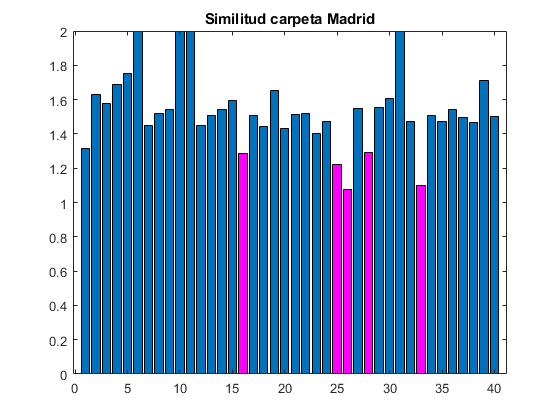

size = 40;
y = zeros(1,size);

for i = 1:size
    novaim = imread(['madrid/',num2str(i),'.jpg']);
    novaimg = rgb2hsv(novaim);
    novanorm = normalizeHSV(novaimg);    
    [h,s] = computeQuadrantsHSV(mh,ms,novanorm,50,0,2,2);
    y(i) = (h+s)/2;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Madrid');

count = 0;
for i = 1:size
    if y(i) < 1.3
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Falsos_positius = [num2str(count/size *100),'%'] 

Falsos_positius = '12.5%'

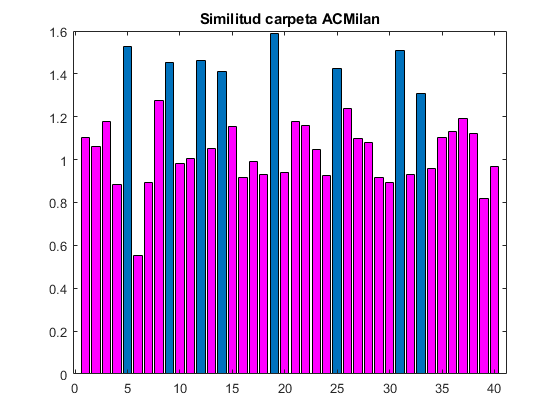

size = 40;
y = zeros(1,size);

for i = 1:size
    novaim = imread(['acmilan/',num2str(i),'.jpg']);
    novaimg = rgb2hsv(novaim);
    novanorm = normalizeHSV(novaimg);    
    [h,s] = computeQuadrantsHSV(mh,ms,novanorm,50,0,2,2);
    y(i) = (h+s)/2;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta ACMilan');

count = 0;
for i = 1:size
    if y(i) < 1.3
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Falsos_positius = [num2str(count/size *100),'%'] 

Falsos_positius = '80%'